## Import the data

 
close all hidden 
clearvars hidden force
clearvars global force
fileNamesStr = "";
[fileNames, folder] = uigetfile('*.csv', 'MultiSelect','on');
warning('off', 'MATLAB:table:ModifiedAndSavedVarnames');
dataTables = cellfun(@(x) readtable(fullfile(folder, x),  'Format','%f%f',"VariableNamingRule","preserve"), fileNames, UniformOutput=false);
[~, fileNames, ~] = fileparts(fileNames);
fileNamesStr = string(fileNames);
fileNamesStr'

ans = 2×1 string array
    "2023.07.04_Kinetik_ProcessedKinetic"
    "2023.07.31_2_Kinetik_.csvProcessedKinetic"


## Check Data

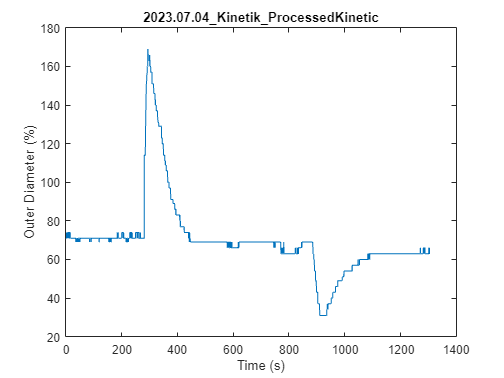

selName = fileNamesStr(1);
index = find(strcmp(fileNamesStr,selName));
plot(dataTables{index},"Time (s)","Outer Diameter (%)")
title(fileNamesStr(index), 'Interpreter','none')

## Select for joining

 
figure()
selectedMeasurements = createSelWindow(fileNamesStr)

selectedMeasurements = 2×1 logical array
   1
   1


indexesSelMeas = find(selectedMeasurements == 1)

indexesSelMeas =      1
     2


close

## Select start

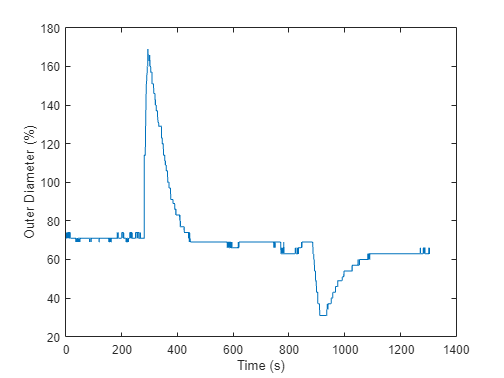

 
timeCorDataTables = dataTables;
joinedNames = fileNamesStr(selectedMeasurements);
for j = indexesSelMeas'
fig = figure;
plot(dataTables{j}, "Time (s)","Outer Diameter (%)");
    shg
    dcm_obj = datacursormode(1);
    set(dcm_obj,'DisplayStyle','window',...
    'SnapToDataVertex','off','Enable','on')
    waitforbuttonpress
    c_info{j} = getCursorInfo(dcm_obj);
    dataIndex{j} = c_info{j}.DataIndex;
close
timeCorDataTables{j}.("Time (s)") = categorical(timeCorDataTables{j}.("Time (s)") - timeCorDataTables{j}.("Time (s)")(dataIndex{j}));
end

## Check Data

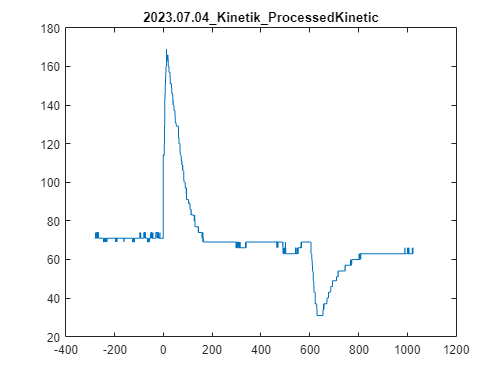

selNameCheck = joinedNames(1);
index = find(strcmp(joinedNames,selNameCheck));

plot(str2double(string(timeCorDataTables{index}.("Time (s)"))),timeCorDataTables{index}.("Outer Diameter (%)"))
title(joinedNames(index), 'Interpreter','none')

## Join

 

timeCorDataTables;
joinedData = outerjoin(timeCorDataTables{indexesSelMeas(1:2)}, "Keys","Time (s)","MergeKeys",true);
for i = 3:numel(indexesSelMeas)
    selIndex = indexesSelMeas(i);
    joinedData = outerjoin(joinedData, timeCorDataTables{selIndex}, "Keys","Time (s)","MergeKeys",true);
end
joinedData.Properties.VariableNames = ["Time (s)"  append("Outer Diameter - ", joinedNames)];
fileNamesStr(indexesSelMeas)'

ans = 2×1 string array
    "2023.07.04_Kinetik_ProcessedKinetic"
    "2023.07.31_2_Kinetik_.csvProcessedKinetic"


joinedData

joinedData = 14370×3 table
    Time (s)    Outer Diameter - 2023.07.04_Kinetik_ProcessedKinetic    Outer Diameter - 2023.07.31_2_Kinetik_.csvProcessedKinetic
    ________    ____________________________________________________    __________________________________________________________

     -281.4                              71                                                         81                            
     -281.3                              71                                                         81                            
     -281.2                              71                                                         81                            
     -281.1                              71                                                         81                            
     -281                                71                                         

## Create Median

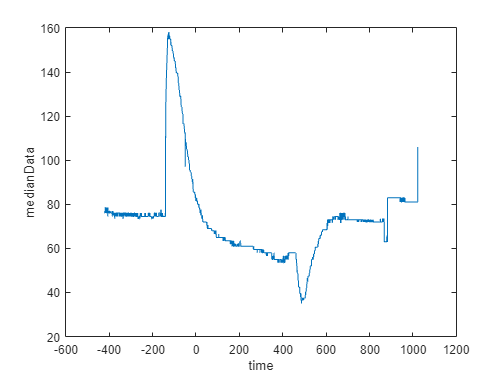

 
addpath stdshade
medianData = median(joinedData{:,2:end}, 2, 'omitmissing');
sdData = std(joinedData{:,2:end},0, 2);
time = sort(double(string(joinedData.("Time (s)"))));
medianTable = table(time, medianData, sdData);
medianTable.observations = repmat(width(joinedData) - 1, size(medianTable,1), 1);
figure
plot(medianTable,"time", "medianData");

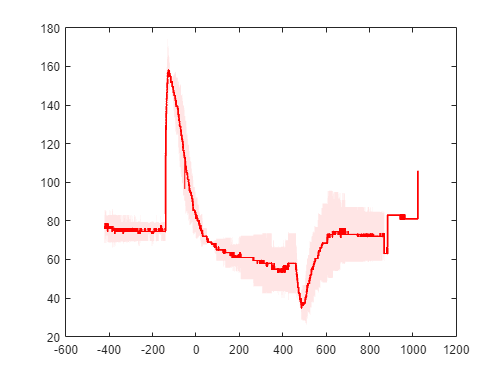

dat = joinedData{:,2:end};
figure
stdshade(dat',0.1, 'r', time);

## Save

 
[file, folder] = uiputfile('.csv');
[~, name ,~] = fileparts(file);

writetable(medianTable, fullfile(folder,append(name, 'Median', '.csv')),'Delimiter',';');
writetable(joinedData, fullfile(folder,append(name, 'Kinetics', '.csv')),'Delimiter',';');

%N in Tabelle
%Joined table als csv

function selectedMeas = createSelWindow(items)
% Create a UIFigure
fig = uifigure('Name', 'Select Measurements');

% Create a GridLayout to arrange the checkboxes
grid = uigridlayout(fig, [2, 1]);

% Create a Checkbox Group
checkboxGroup = uibuttongroup(grid, 'Title', 'Select Items', 'AutoResizeChildren', 'off', 'Position', [10, 10, 180, 180]);
checkboxGroup.Scrollable = 'on';

% Create checkboxes
numItems = numel(items);
checkboxes = cell(numItems, 1);
for i = 1:numItems
    checkboxes{i} = uicheckbox(checkboxGroup, 'Text', items{i}, 'Position', [10, 150 - (i - 1) * 30, 500, 22]);
end

% Create a button to retrieve the selected items
retrieveButton = uibutton(grid, 'Text', 'Get Selection', 'ButtonPushedFcn', @(btn, event) getSelection(checkboxes, numItems));

% Initialize an array to store selected items
selectedMeas = cell(numItems, 1);

% Display the UIFigure
fig.Visible = 'on';

% Wait for the figure to be closed (optional)
waitfor(fig);
    function selectedItems = getSelection(checkboxes,numItems)
        for i = 1:numItems
            selectedMeas{i} = checkboxes{i}.Value;
        end
        selectedMeas =  cell2mat(selectedMeas);
           close(fig);
    end
end